%% Script to fit a 1st order PK model to the 3rd order dynamics from Jost 2020

% Setup
clear;clc;

% Params from Jost 2020 PK
F = 0.22;
k_a = 31.2;
k_20 = 12.72;
FM3kme = 0.019;
k_me = 9.9216;
BSA = 1;
CL6tgn = 0.219 * BSA ^ 1.16;

% Create a 3rd order state space model
A = [-k_a, 0, 0;
     k_a, -k_20, 0;
     0, FM3kme, -CL6tgn];
B = [F; 0; 0];
C = [0, 0, 1];
D = 0;

sys_3rd_order = ss(A, B, C, D);

% Step response of the 3rd order model ---
dose = 200;
dt = 0.01;
Ndays = 100;
t = dt:dt:Ndays;
u_singleDay = [dose; zeros(1/dt-1,1)];
u = repmat(u_singleDay, Ndays, 1);

% Calculate the step response.
y_3rd_order = lsim(sys_3rd_order, u, t);

% Create 1st order model
F_over_V =0.00033/ BSA;
k_e =-0.22;

sys_1st_order = ss(k_e, F_over_V, 1, 0);

% Step Response of the 1st order model
y_1st_order = lsim(sys_1st_order, u, t);

% --- Plot the Step Responses for Visual Comparison ---
figure;
plot(t, y_3rd_order, 'b', 'LineWidth', 2);
hold on;
plot(t, y_1st_order, 'r', 'LineWidth', 1);
hold off;

% Calculate mean absolute error (MAE)
mae = mean(abs(y_3rd_order - y_1st_order));
disp(['Mean Absolute Error (MAE): ', num2str(mae)]);

Mean Absolute Error (MAE): 0.00010143



% Calculate RMSE
rmse = sqrt(mean((y_3rd_order - y_1st_order).^2));
disp(['Root Mean Square Error (RMSE): ', num2str(rmse)]);

Root Mean Square Error (RMSE): 0.00015438


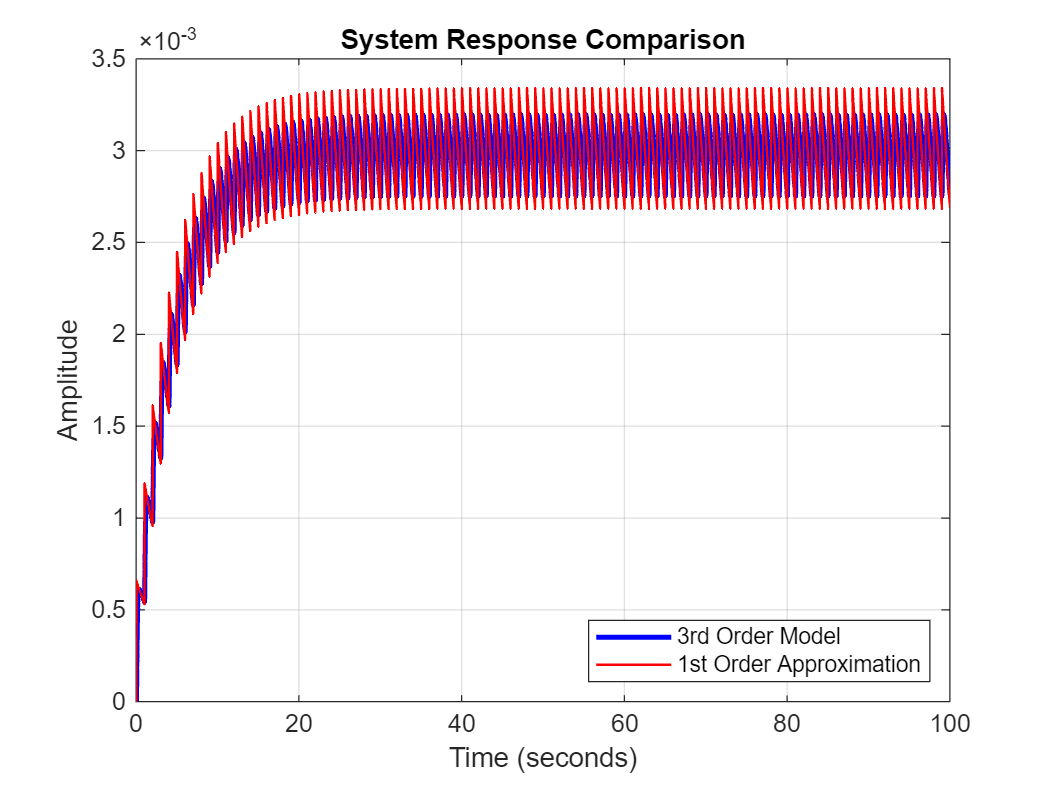


% --- Add plot details for clarity ---
title('System Response Comparison');
xlabel('Time (seconds)');
ylabel('Amplitude');
legend('3rd Order Model', '1st Order Approximation','location','southeast');
grid on;


% --- Display the tuned parameters ---
disp('Tuned 1st Order Model Parameters:');

Tuned 1st Order Model Parameters:


disp(['Gain (F/V): ', num2str(F_over_V)]);

Gain (F/V): 0.00033


Time Constant (k_e): -0.22


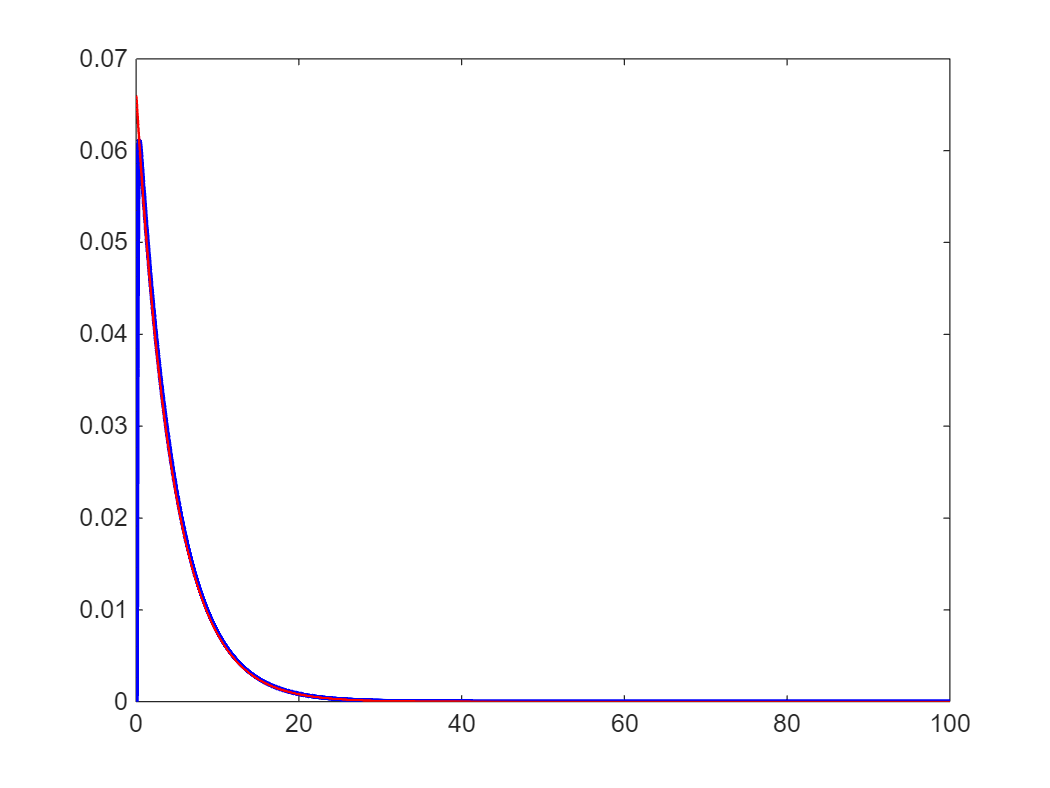

disp(['Time Constant (k_e): ', num2str(k_e)]);